# Segmentació per GLCM

## Netejar l'entorn

clc
close all
clear variables

## Parameters

samplePath = 'DemoPratFullAltMicro.png';
scenePath = 'DemoPratFullAlt.png';

% Co-matrix settings
cmDist = 1;
cmDir = [0 1; 1 0; 1 1; -1 1];
cmSym = true; % Symmetric (offsets [1 0] == [-1 0])

% Sliding Window settings
swStep = 10;

% Classification settings
nbest = 0; % Show best nbest cases. If 0, show cases better than threshold.
thr = 0.9;

## Processem la mostra

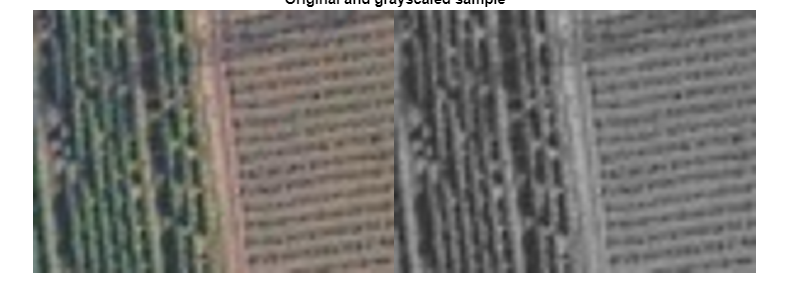

sampleImg = imread(samplePath);
sampleImgGs = im2gray(sampleImg);

figure
montage({sampleImg, sampleImgGs}), title('Original and grayscaled sample');


sampleCM = graycomatrix(sampleImgGs, Offset = cmDir*cmDist, Symmetric = cmSym);
sampleProps = graycoprops(sampleCM)

sampleProps = struct with fields:
       Contrast: [0.7418 0.4980 0.9648 0.9964]
    Correlation: [0.5382 0.6884 0.3977 0.3780]
         Energy: [0.1276 0.1399 0.1091 0.1058]
    Homogeneity: [0.7379 0.7790 0.6599 0.6639]


sampleProps = cell2mat(struct2cell(sampleProps));

## Girem la mostra (no utilitzada encara)

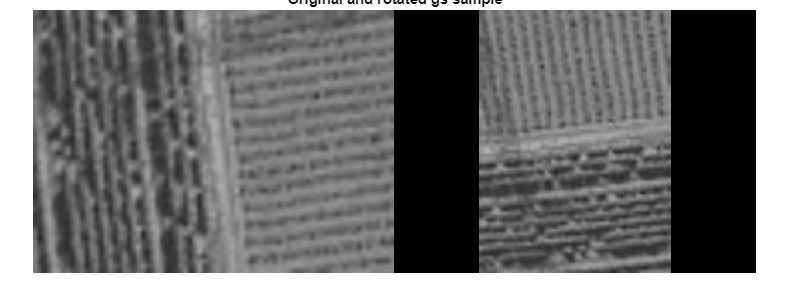

sample2ImgGs = rot90(sampleImgGs);

figure
montage({sampleImgGs, sample2ImgGs}), title('Original and rotated gs sample');


sample2CM = graycomatrix(sample2ImgGs, Offset = cmDir*cmDist, Symmetric = cmSym);
sample2Props = graycoprops(sample2CM);
sample2Props = cell2mat(struct2cell(sample2Props));

a = sampleProps - sample2Props

a =     0.2438   -0.2438   -0.0316    0.0316
   -0.1502    0.1502    0.0198   -0.0198
   -0.0123    0.0123    0.0033   -0.0033
   -0.0411    0.0411   -0.0040    0.0040


sum(abs(a), 'all')

ans = 1.0119

## Processem l'escena

sceneImg = imread(scenePath);
sceneImgGs = im2gray(sceneImg);

## Busquem coincidencies

swSize = size(sampleImgGs); % Sliding window must match sample size
swNumY = floor( (size(sceneImgGs,1)-swSize(1)) / swStep )

swNumY = 102

swOffsetsY = swStep*(1:swNumY);

swNumX = floor( (size(sceneImgGs,2)-swSize(2)) / swStep )

swNumX = 245

swOffsetsX = swStep*(1:swNumX);

err = NaN(swNumY, swNumX);

figure,
imshow(sceneImg), hold on;

tic;
for ny = 1:swNumY

    y = swOffsetsY(ny);

    for nx = 1:swNumX

        x  = swOffsetsX(nx);

        %fprintf('Y: %i,%i %i\n', y, y+swSize(1), y+swSize(1) <= size(sceneImgGs,1));
        swSample = sceneImgGs(y:(y+swSize(1)), x:(x+swSize(2)));

        swCM = graycomatrix(swSample, Offset = cmDir*cmDist, Symmetric = cmSym);
        swProps = graycoprops(swCM);
        swProps = cell2mat(struct2cell(swProps));

        err(ny, nx) = sum( abs(sampleProps - swProps), 'all');

        if err(ny, nx) <= thr
            %fprintf('P1: %i,%i\n P2: %i,%i\n', x, y, x+swSize(2), y+swSize(1));
            rectangle(Position = [x y swSize(2) swSize(1)], EdgeColor = 'r', LineWidth = (1+rem((nx + ny), 3)));
        end
    end
end
toc

Elapsed time is 15.550585 seconds.


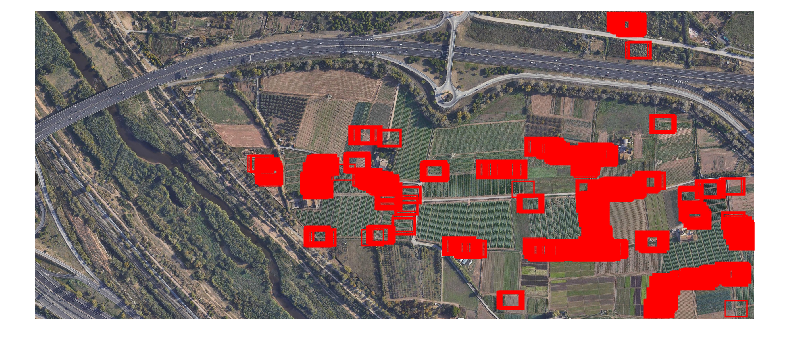


%rectangle(Position = [1 1 800 800], EdgeColor = 'r', LineWidth = 1)
hold off